# Task 1

disp("Task 1")

Task 1


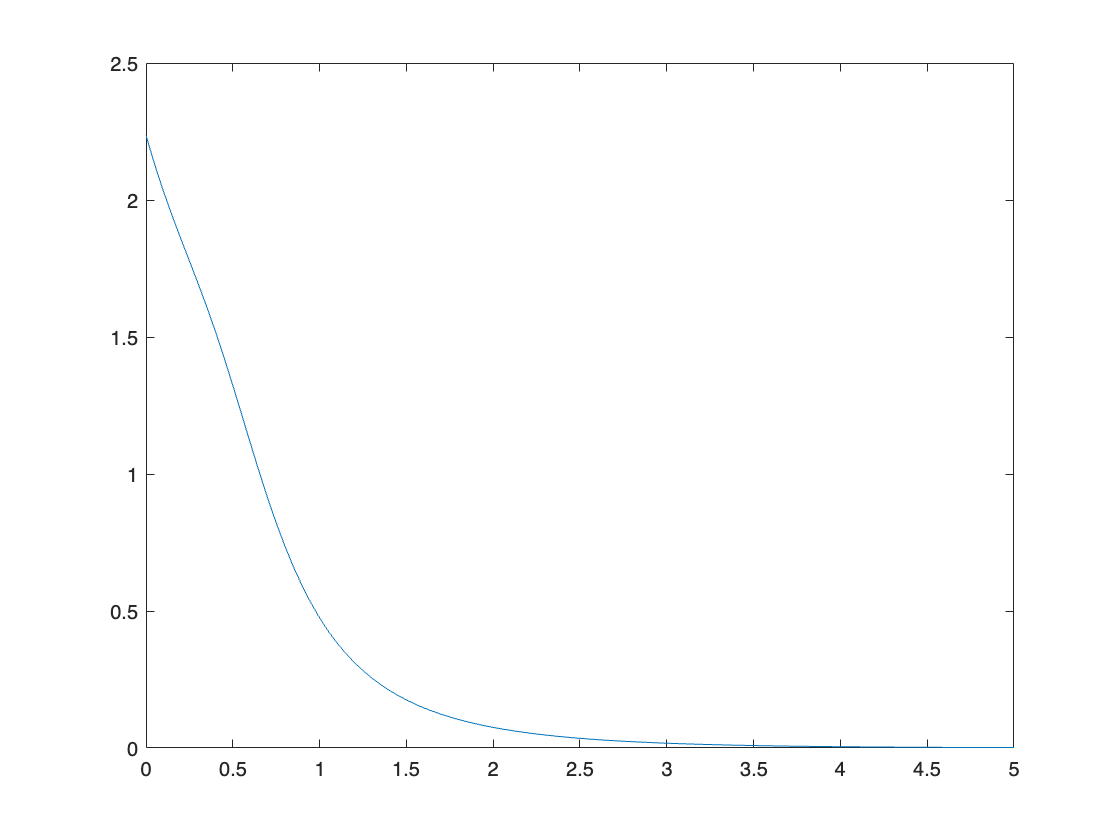

x = 0:0.05:5;
y = myfun1(x);
plot(x,y)

## Task 2

disp("Task 2")

Task 2


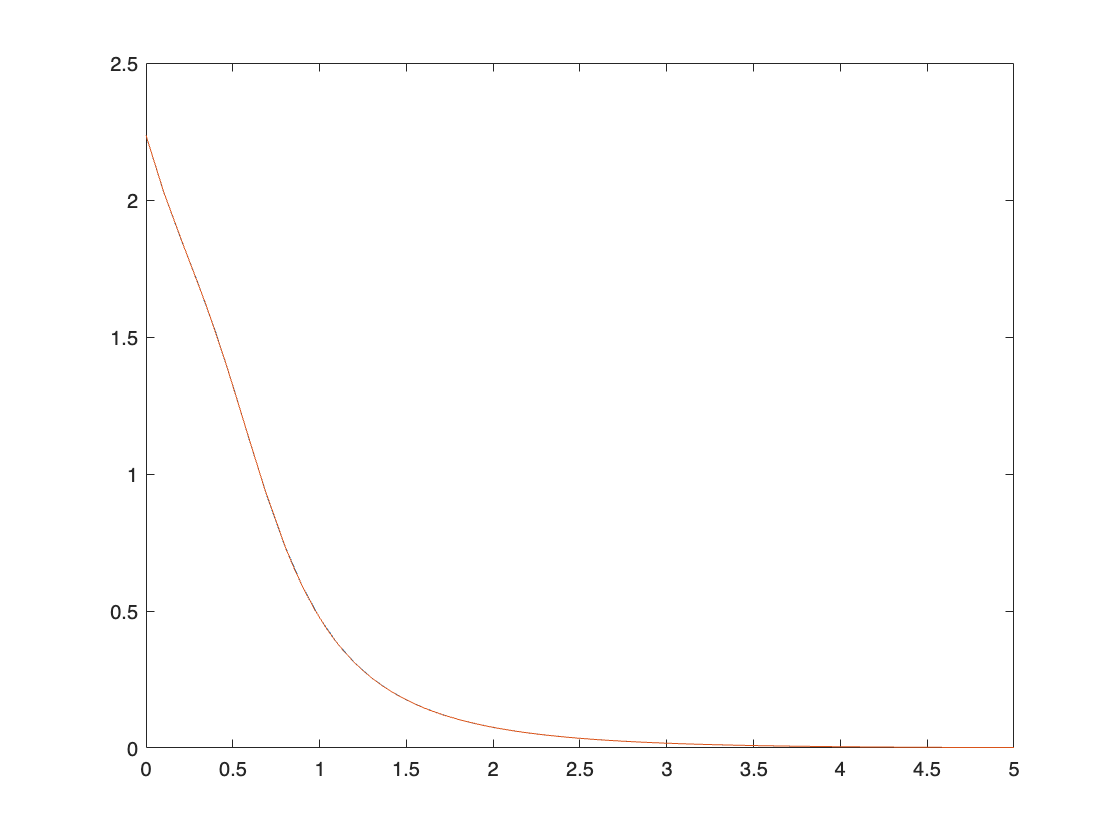

x = 0:0.1:5;
y = myfun1(x);
figure 
plot(x,y)
fplot(@myfun1, [0 5])

lookfor myfun1

myfun1                         - Функция myfun1


help myfun1

  Функция myfun1
  f = exp(-x).*sqrt((x.^2+1)/(x.^4+0.2));



## Task 3

disp("Task 3")
a = input("Введите вектор:");
x = suma(a)

x = 4

## Task 4

disp("Task 4")

Task 4


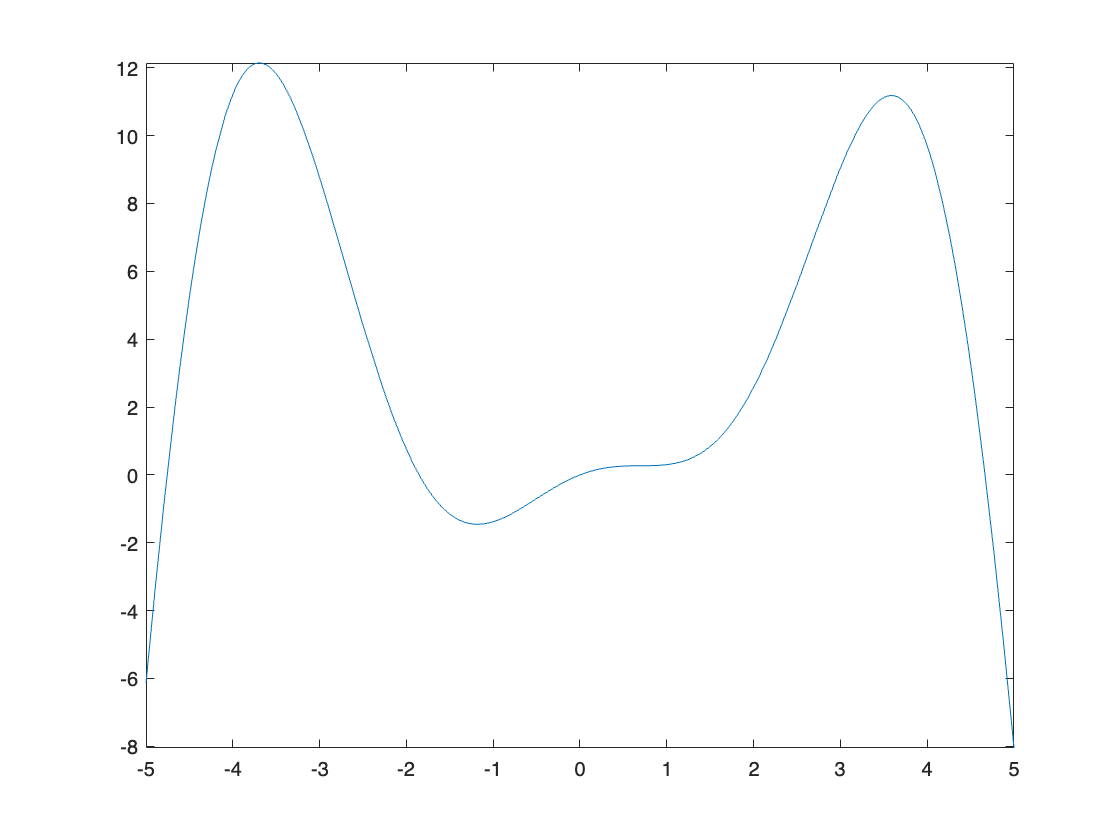

figure
grid on
fplot(@myfun2, [-5 5])

x1 = fzero(@myfun2, -4.8)

x1 = -4.7566

x2 = fzero(@myfun2, -1.9)

x2 = -1.8539

x3 = fzero(@myfun2, 0)

x3 = 0

x4 = fzero(@myfun2, 4.7)

x4 = 4.6665

## Task 5

disp("Task 5")

Task 5


polynom = [1 0 0 0 0 3 1 -10 -1 1024];
r = roots(polynom)

r =   -2.1627 + 0.0000i
  -1.6483 + 1.3734i
  -1.6483 - 1.3734i
  -0.3898 + 2.1481i
  -0.3898 - 2.1481i
   1.0978 + 1.8552i
   1.0978 - 1.8552i
   2.0216 + 0.7464i
   2.0216 - 0.7464i


polyval(polynom, r)

ans = 1.0e-11 *

   0.1364 + 0.0000i
   0.0000 - 0.0682i
   0.0000 + 0.0682i
  -0.0682 + 0.0369i
  -0.0682 - 0.0369i
  -0.5684 - 0.1421i
  -0.5684 + 0.1421i
   0.0000 - 0.0512i
   0.0000 + 0.0512i


## Task 6

disp("Task 6")

Task 6


figure;
grid on;
hold on;
syms x;
func6 = inline('exp(x.^2) + sin(3 * pi * x)');

min1 = fminbnd(func6, -0.9, -0.6) 

min1 = -0.7987

min2 = fminbnd(func6, -0.4, 0)

min2 = -0.1629

min3 = fminbnd(func6, 0.4, 0.7)

min3 = 0.4861

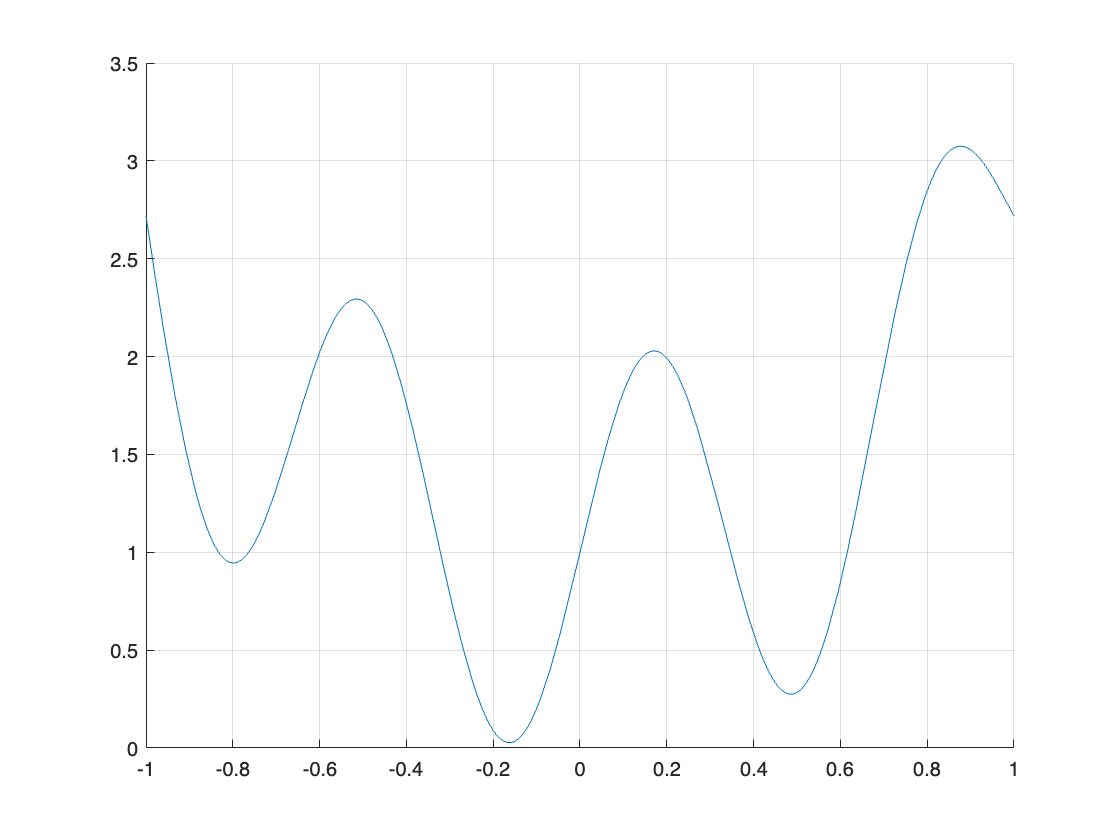


fplot(func6(x), [-1 1])

## Task 7

disp("Task 7")

Task 7


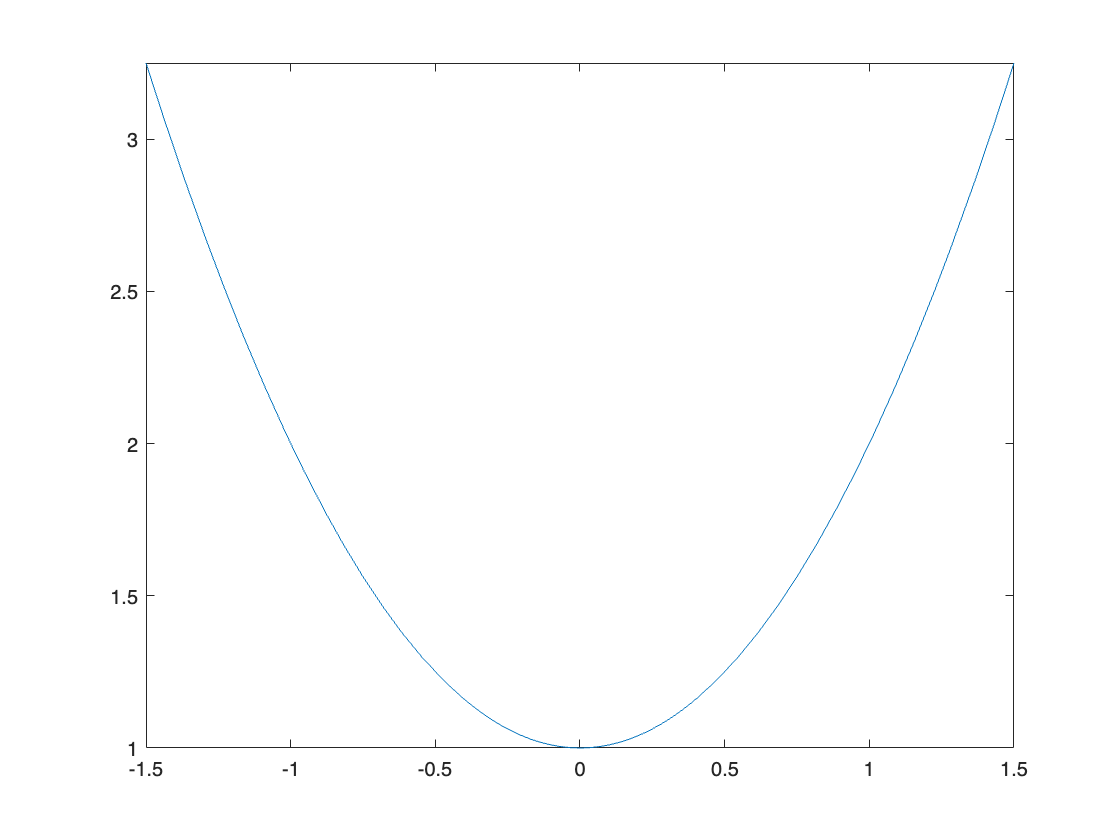

f7 = @(x)x.^2+1;
figure
fplot(f7(x), [-1.5 1.5])

x1 = fminbnd(f7, -1, 1)

x1 = -1.1102e-16

## Task 8

disp("Task 8")

Task 8


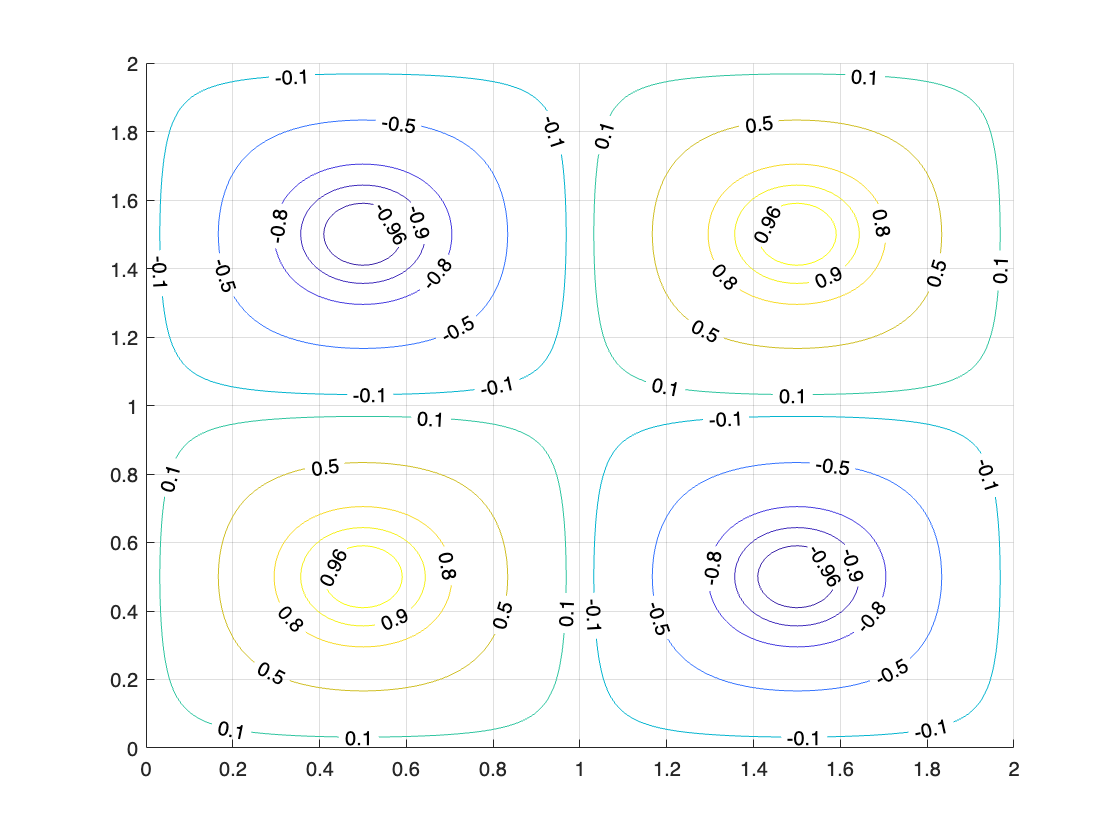

figure;
grid on;
hold on;
[X,Y] = meshgrid(0:0.01:2);
Z = sin(pi*X).*sin(pi*Y);
[C, H] = contour(X, Y, Z, [-0.96, -0.9, -0.8, -0.5, -0.1, 0.1, 0.5, 0.8, 0.9, 0.96]);
clabel(C, H)


[Min1, fmin1] = fminsearch(@myfun8, [1.3, 0.7])

Min1 =     1.5000    0.5000


fmin1 = -1.0000

[Min2, fmin2] = fminsearch(@myfun8, [0.7, 1.5])

Min2 =     0.5000    1.5000


fmin2 = -1.0000


[Max1, fmax1] = fminsearch(@myfun8_2, [0.4, 0.6])

Max1 =     0.5000    0.5000


fmax1 = -1.0000

[Max2, fmax2] = fminsearch(@myfun8_2, [0.7, 1.5])

Max2 =     1.5000    1.5000


fmax2 = -1.0000

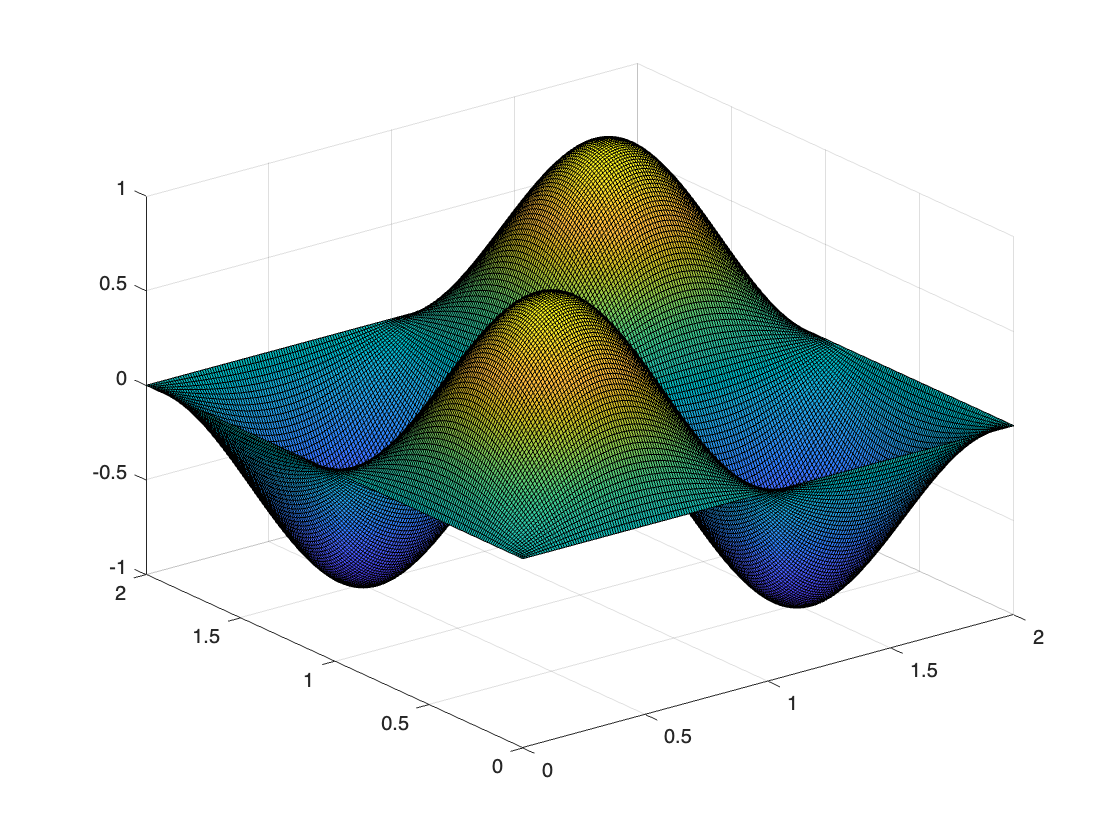


figure;
surf(X,Y,Z) 

## Functions

function f = myfun2(x)
f = sin(x) - (x.^2).*cos(x);
end